clc
clear
clear global

global  A b  n_ele  iter type
stru_num=3;
for iter=1:stru_num
    tic
    filename=['CONTCAR',num2str(iter-1)];
    [C, S] = read_poscar(filename);

    S0 = S * C;
    expand = [];
    num = get_num(filename);
    S_C = S0(1:num.C, :);

    for ii = 0:1
        for jj = 0:1
            expand = [expand; S_C + ii * C(1, :) + jj * C(2, :)];
        end
    end


    % 初始化变量
    bond = [];
    D = [];
    dis = zeros(size(S_C, 1), size(expand, 1));

    % 计算原子之间的距离
    for ii = 1:size(S_C, 1)
        if mod(ii,1000)==0
            ii
        end
        for jj = 1:size(expand, 1)
            dis(ii, jj) = norm(S_C(ii, :) - expand(jj, :));
            if abs(dis(ii, jj) - 1.4) < 0.3
                bond = [bond; ii, mod(jj - 0.5, size(S_C, 1)) + 0.5];
                D = [D, dis(ii, jj)];
            end
        end
    end

    % 去重和排序
    bond = sort(bond, 2);
    [bond, ia, ic] = unique(bond, "rows");
    D = D(ia);

    % 统计每个原子的键数量
    qq = tabulate(bond(:));
    edge_H = qq(find(qq(:, 2) == 2), 1);
    bond = [bond, D'];


    type{iter}=get_type(bond(:,1:2),S_C,C);


    num_vars = size(bond,1);
    A{iter} = zeros(size(S_C,1)+1,num_vars);


    for ii = 1:size(S_C,1)
        [a,~] =  find(bond(:,1:2) == ii);
        for k = 1:length(a)
            [~,idx] = ismember(bond(a(k),1:2),bond(:,1:2),'rows');
            A{iter}(ii,idx) = A{iter}(ii,idx) + 1;
        end
    end

    for ii = 1:size(bond,1)

        A{iter}(end,ii) = A{iter}(end,ii) + 1;
    end

    b{iter} = [ones(size(S_C,1),1)*4;2*num.C-0.5*num.H];
    b{iter}(edge_H)=3;
    n_ele(iter) = max(b{iter});

    x0=rand(1,size(A{iter},2));
    fun=@(x) fun1(x);
    options = optimoptions('fmincon','Display','notify','Algorithm','sqp',...
        'MaxFunctionEvaluations',100000);
    [x{iter}, F(iter)]=fmincon(fun,x0,[],[],A{iter},b{iter},ones(1,size(A{iter},2)),2*ones(1,size(A{iter},2)),[],options);

    BOND{iter}=[bond,x{iter}'];
    BOND{iter}(:,3:4)=round(BOND{iter}(:,3:4),4);
%   writematrix(BOND{iter},[num2str(iter-1),'-S_data.txt'],"Delimiter",' ')
    toc
end

历时 0.042092 秒。
历时 0.045391 秒。
历时 0.046788 秒。


## Visualization

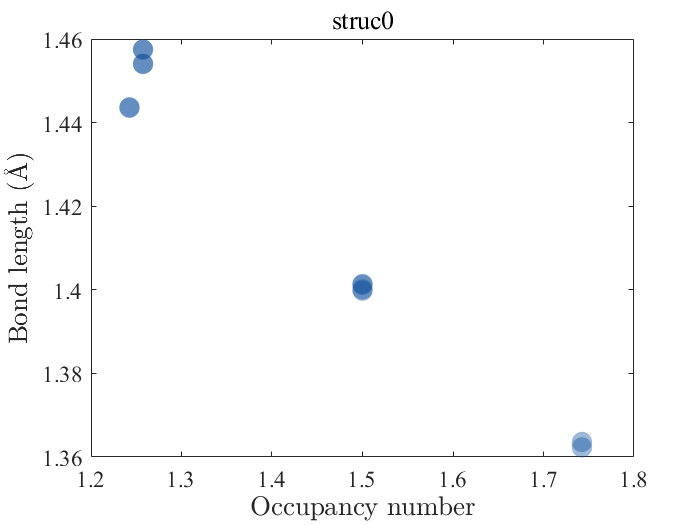

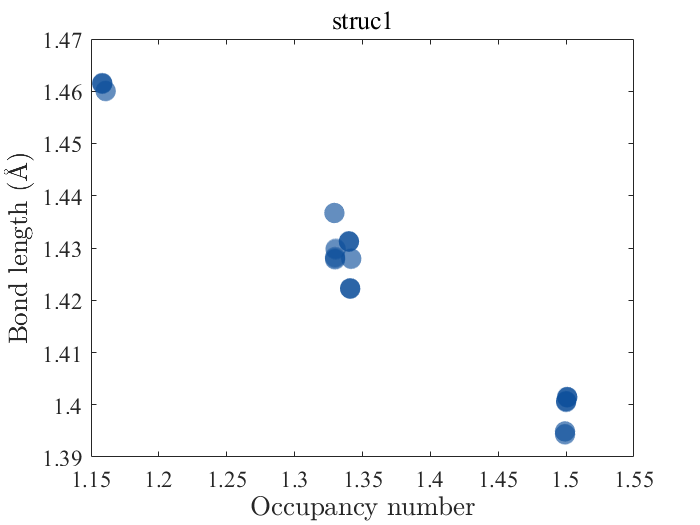

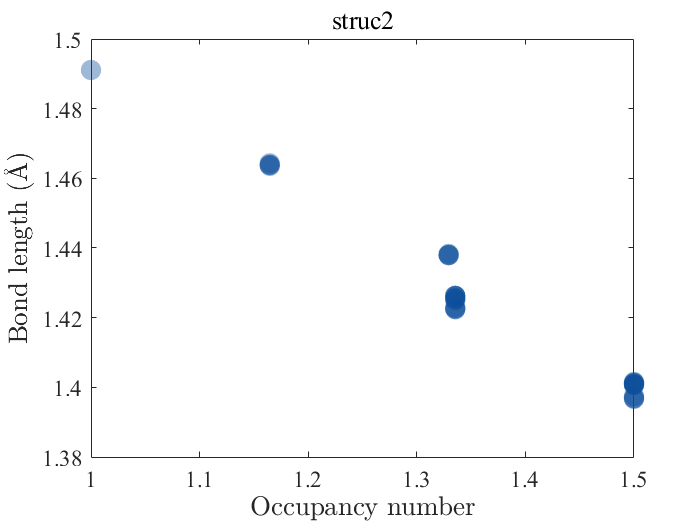


for iter=1:stru_num
    figure
    scatter(BOND{iter}(:,4),BOND{iter}(:,3),150,[12,78,155]/256,'o',"filled")
    hold on
    box on
    alpha(0.4)
    set(gca,"FontName",'Times New Roman',"FontSize",14)
    title(['struc',num2str(iter-1)])
    xlabel('Occupancy number','Interpreter','latex',"FontSize",16,"FontName",'Times New Roman')
    ylabel('Bond length (\AA)','Interpreter','latex',"FontSize",16,"FontName",'Times New Roman')


end